close all; clear; clc;

# Custom Steps Sequence Test 2

test2: test2.mlx

**keywords:** custom steps sequence, test 2

**file created by:** {20180709, Edmonds}

**last updated on:** {20180709}

**primary purpose:** Determine the best way to utilize the Custom Step Sequence Script

**primary input and output variables: **

calculated/not measured from test stand- motor radius and rho. 

measured from test stand- time, ESC us, Torque, Thrust, input voltage, input current, rotational speed (omega), input power, output power, efficiencies (motor, prop, overall), temp probe (by motor)

**functions:** [C_T], [C_P], [C_Q]

**Notes:** 

## Input Variables

% Air Density
p = 0.00230529925626351;                  %[slugs/ft^3]

% Motor Specs
radius = 7.5/12;               % [ft]
area = pi * radius^(2);       % [ft^2]

## Measured Data

This format assumes that the "servo" column was deleted beforehand

load('20180709_test2.mat');
time = test2(:,1);          % [sec]
ESC_us = test2(:,2);        % [micro sec] (this is how quickly the ESC is providing voltage to the motor -- translates to throttle% ?
Q = test2(:,3);             % [ft.lbf]
T = test2(:,4);             % [lbf]
Input_V = test2(:,5);       % [Volts]
Input_A = test2(:,6);       % [Amps]
rot_speed = test2(:,7);     % [rad/sec]
P_in_W = test2(:,8);        % [Watts]
P_out_W = test2(:,9);        % [Watts]
% convert to [ft.lbf/sec]
P_out = P_out_W .* 0.7478;     % [ft.lbf/sec]         
P_in = P_in_W .* 0.7478;       % [ft.lbf/sec]

Motor_Eff = test2(:,10);    % [%]
Prop_Eff = test2(:,11);     % [lbf/Watts]
Overall_Eff = test2(:,12);  % [lbf/Watts]  
Motor_Temp = test2(:,13);   % [F]


## Thrust, Power, and Torque Coefficents

C_T = T ./ (p .* area * (rot_speed * radius).^2);
C_P = P_out ./ (p .* area .* (rot_speed .* radius).^3);
C_Q = Q ./ (p .* area .* (rot_speed .* radius).^(2) .* radius);

## Plots

{This is the section for generating output tables, plots, etc.}

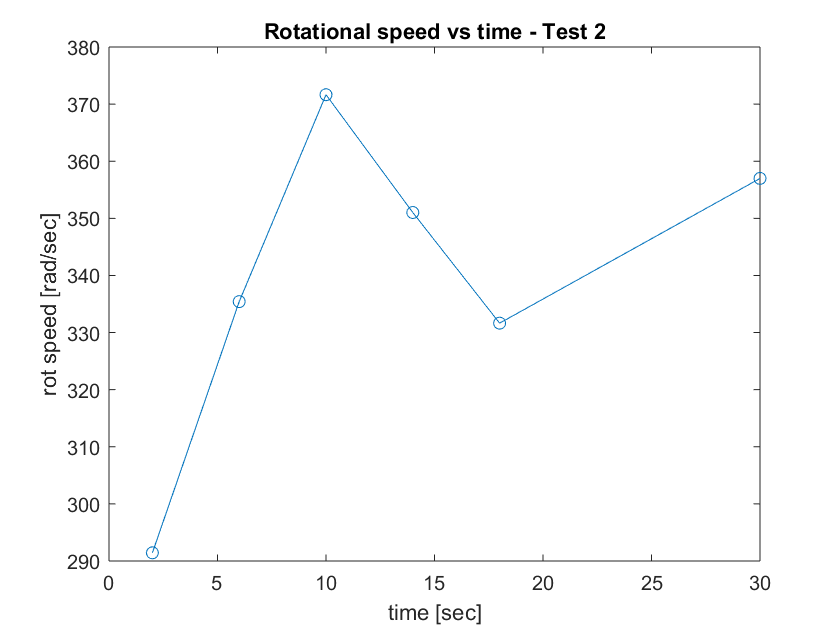

figure(1)
plot(time, rot_speed, 'o-'); title('Rotational speed vs time - Test 2');
xlabel('time [sec]'); ylabel('rot speed [rad/sec]');

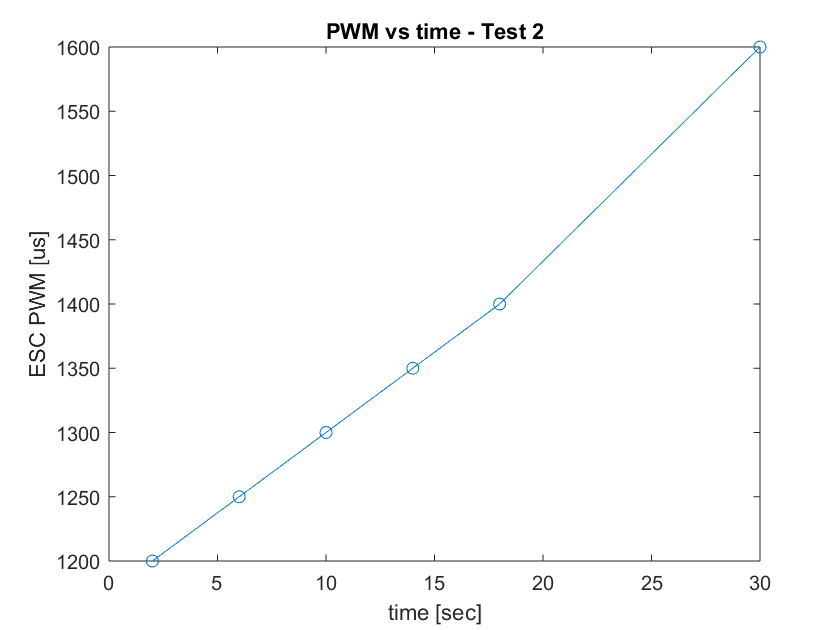


figure(2)
plot(time, ESC_us, 'o-'); title('PWM vs time - Test 2');
xlabel('time [sec]'); ylabel('ESC PWM [us]');